#### 1. Função de Transferência do sistema

a = 10.4167;
s = tf('s');
Kp = 595;
Ts = 0.008; % Período de amostragem (Ts = 8ms)
Gp = a * Kp /(s+a);
Gp_zpk = zpk(Gp)

Gp_zpk =
 
   6197.9
  ---------
  (s+10.42)
 
Continuous-time zero/pole/gain model.
Model Properties


#### 2. Modelo em espaço de estado


$$\dot{\mathbf{x}}(t) = \mathbf{A}\mathbf{x}(t) + \mathbf{B}\mathbf{u}(t) \\
\mathbf{y}(t) = \mathbf{C}\mathbf{x}(t) + \mathbf{D}\mathbf{u}(t)
$$


[num, den] = tfdata(Gp, 'v'); 
[Ac, Bc, Cc, Dc] = tf2ss(num, den);

#### 3. Sistem em espaço de estados

sys = ss(Ac, Bc, Cc, Dc) % Sistema tempo contínuo

sys =
 
  A = 
           x1
   x1  -10.42
 
  B = 
       u1
   x1   1
 
  C = 
         x1
   y1  6198
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


#### 3.1 Resposta ao degrau

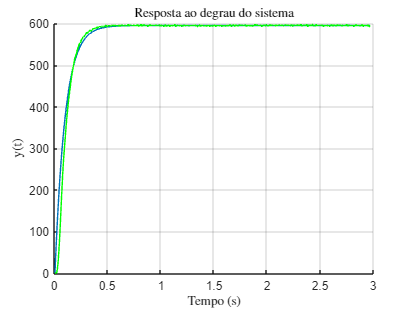

dados = readtable('./Remodelando/saida-156.csv');

t8ms = 1:length(dados.Tempo);
t8ms = t8ms * 8e-3;

[yp, tp] = step(sys, t8ms);

f = figure;
hold on;
plot(tp, yp);
plot(t8ms, dados.Saida, color='g');
title('Resposta ao degrau do sistema', 'Interpreter', 'latex');
ylabel('y(t)', 'Interpreter', 'latex');
xlabel('Tempo (s)', 'Interpreter', 'latex');
grid on;
exportgraphics(f, './Resultados/Sistema.pdf', 'ContentType', 'vector');

#### 4.  Projetando o Controlador

**4.1 Avaliando Controlabilidade e Observabilidade**

%% Controlabilidade

Sz = Bc;

if length(Sz)==1
    if Sz~=0
        fprintf("É controlável.");
    else
        fprintf("Não é controlável.");
    end
else
    if det(Sz)~=0
        fprintf("É controlável.");
    else
        fprintf("Não é controlável.");
    end
end

É controlável.

% Convertendo para FCC

Q1_c = 1 * Sz^(-1);

Q_c = Q1_c;

Ax_fcc = Q_c*Ac*Q_c^(-1)

Ax_fcc = -10.4167

Bx_fcc = Q_c*Bc

Bx_fcc = 1

Cx_fcc = Cc*Q_c^(-1)

Cx_fcc = 6.1979e+03

Sx = Bx_fcc;

P_c = Sz*Sx^(-1);

% Observabilidade

Vz = Cc;

if length(Vz)==1
    if Vz~=0
        fprintf("É observável.");
    else
        fprintf("Não é observável.");
    end
else
    if det(Vz)~=0
        fprintf("É observável.");
    else
        fprintf("Não é observável.");
    end
end

É observável.

% Convertendo para FCO

Q1_o = Cc^(-1) * 1;

Q_1_o = Q1_o;

Q_o = Q_1_o^(-1);

Ax_fco = Q_o*Ac*Q_1_o

Ax_fco = -10.4167

Bx_fco = Q_o*Bc

Bx_fco = 6.1979e+03

Cx_fco = 1

Cx_fco = 1

Vx = Cx_fco;

P_o = Vz^(-1)*Vx;

**4.2 Aplicando LQI**

% Construção do sistema aumentado

Ae = [Ac 0;
       -Cc 0]

Ae = 1.0e+03 *

   -0.0104         0
   -6.1979         0


Be = [Bc; 0]

Be =      1
     0


Ce = [Cc 0]

Ce = 1.0e+03 *

    6.1979         0


De = 0;

sys_E = ss(Ae, Be, Ce, De);
% Definição das matrizes Q e R

Q_c = 1.2 * eye(1); % Aumentar Q em relação a R: x(t)->0 mais rapidamente esforço de controle u(t) maior
R_c = 2.0 * eye(1); % Aumentar R em relação a Q: u(t) é menor e x(t) tende a uma resposta superamortecida 

% Por função LQR e sistema expandido
[Ke, Se, Pe] = lqr(sys_E, Q_c, R_c)

Ke =    88.1272   -0.7746


Se =   176.2545   -1.5492
   -1.5492    0.0246


Pe =  -49.2720 +48.7152i
 -49.2720 -48.7152i


% Por função LQI com sistema em tempo contínuo
[Kteste, Steste, Pteste] = lqi(sys, Q_c, R_c)

Kteste =    88.1272   -0.7746


Steste =   176.2545   -1.5492
   -1.5492    0.0246


Pteste =  -49.2720 +48.7152i
 -49.2720 -48.7152i


K  = Ke(1:end-1)

K = 88.1272

Ki = -Ke(end)

Ki = 0.7746


% Sistema em malha fechada com integrador
A_cl = [Ac - Bc*K, Bc*Ki;
            -Cc      ,  0];

B_cl = [0; 1];  % Entrada de referência
C_cl = [Cc 0];
D_cl = 0;

sys_cl = ss(A_cl, B_cl, C_cl, D_cl);
sys_tf = tf(sys_cl);  % Converte espaço de estados para FT

[y, tOut] = step(sys_tf, t8ms);

zpk(sys_tf)           % Exibe zeros, polos e ganho

ans =
 
         4800.9
  ---------------------
  (s^2 + 98.54s + 4801)
 
Continuous-time zero/pole/gain model.
Model Properties


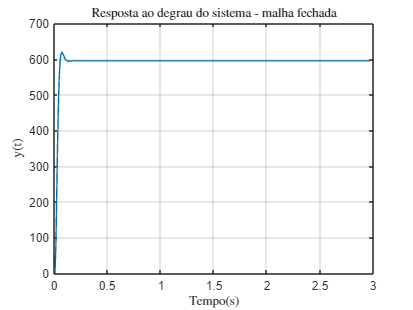


% Plotagem dos estados
f = figure;
plot(tOut, y*Kp);
title('Resposta ao degrau do sistema - malha fechada', 'Interpreter', 'latex');
ylabel('y(t)', 'Interpreter', 'latex');
xlabel('Tempo(s)','Interpreter', 'latex');
grid on;
exportgraphics(f, './Resultados/Cotrolador.pdf', 'ContentType', 'vector')

**Discretização do sistema**

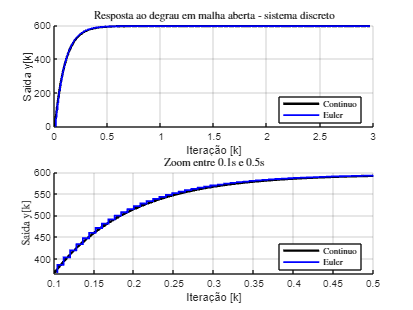

n = size(Ac);

Aeuler =  eye(n) + Ts * sys.A; 
Beuler =  Ts * sys.B;
Ceuler = sys.C;
Deuler = sys.D;
sys_euler = ss(Aeuler, Beuler, Ceuler, Deuler, Ts);

t = t8ms;
u = ones(size(t)); % Degrau unitário

% Respostas dos sistemas
[y_cl, ~, ~]               = lsim(sys, u, t);       % Contínuo
[y_euler, time_euler, ~]      = lsim(sys_euler, u, t);    % Discretizado Euler

% Criação da figura com dois subplots
f = figure;

% --- Subplot 1: Janela de tempo completa
subplot(2,1,1);
hold on;
plot(t, y_cl,     'k-',  'LineWidth', 2,   'DisplayName', 'Continuo');
stairs(t, y_euler, 'b-',  'LineWidth', 1.5, 'DisplayName', 'Euler');
legend('Location','best', 'Interpreter','latex');
xlabel('Iteração [k]');
ylabel('Saida y[k]');
title('Resposta ao degrau em malha aberta - sistema discreto', 'Interpreter','latex');
grid on;

% --- Subplot 2: Zoom em 0.1 a 0.5 segundos
subplot(2,1,2);
hold on;
plot(t, y_cl,     'k-',  'LineWidth', 2,   'DisplayName', 'Continuo');
stairs(t, y_euler, 'b-',  'LineWidth', 1.5, 'DisplayName', 'Euler');
xlim([0.1 0.5]);
legend('Location','best', 'Interpreter','latex');
xlabel('Iteração [k]');
ylabel('Saida y[k]', 'Interpreter','latex');
title('Zoom entre 0.1s e 0.5s', 'Interpreter','latex');
grid on;

% Exporta tudo em um único PDF
exportgraphics(f, './Resultados/Discretização.pdf', 'ContentType', 'vector');

### **Aplicando o controlador **

N = length(t8ms);
R = 595;

#### III. Euler

[y_euler, u_euler, x_euler, e_euler, xn_euler] = ApplyController(sys_euler, K, Ki, N, Ts, R);

#### Resultados 

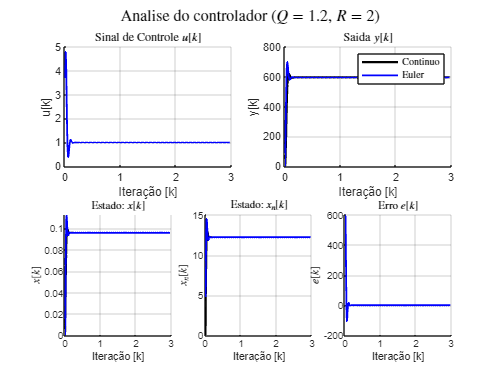

u = ones(size(t)); % Degrau unitário

[y_cl, time_cl, x_cl] = lsim(sys_cl, u, t);  % Contínuo
f = figure;

% --- Subplot 1: Sinal de Controle u[k]
subplot(2,2,1);
hold on;
plot(t, u_euler, 'b-', 'LineWidth', 1.5);
xlabel('Iteração [k]');
ylabel('u[k]');
title('Sinal de Controle $u[k]$', 'Interpreter', 'latex');
grid on;

% --- Subplot 1: Estado xk
subplot(2,3,4);
hold on;
plot(t, x_cl(:,1) * R, 'k-', 'LineWidth', 1.5); 
plot(t, x_euler, 'b-', 'LineWidth', 1.5);
hold off;
title('Estado: $x[k]$', 'Interpreter', 'latex');
xlabel('Iteração [k]');
ylabel('$x[k]$', 'Interpreter', 'latex');
grid on;

% --- Subplot 2: Estado xn
subplot(2,3,5);
hold on;
plot(t, x_cl(:,2) * R, 'k-', 'LineWidth', 1.5); 
plot(t, xn_euler, 'b-', 'LineWidth', 1.5);
hold off;
title('Estado: $x_n[k]$', 'Interpreter', 'latex');
xlabel('Iteração [k]');
ylabel('$x_n[k]$', 'Interpreter', 'latex');
grid on;


% --- Subplot 3: Erro
subplot(2,3,6);
hold on;
plot(t, e_euler, 'b-', 'LineWidth', 1.5);
xlabel('Iteração [k]');
ylabel('$e[k]$', 'Interpreter', 'latex');
title('Erro $e[k]$', 'Interpreter', 'latex');
grid on;

% --- Subplot 4: Saída
subplot(2,2,2);
hold on;
plot(t, y_cl * R, 'k-', 'LineWidth', 2, 'DisplayName', 'Contínuo');
plot(t, y_euler, 'b-', 'LineWidth', 1.5);
xlabel('Iteração [k]');
ylabel('y[k]');
title('Saida $y[k]$', 'Interpreter', 'latex');
grid on;


sgtitle(sprintf('Analise do controlador ($Q = %g$, $R = %g$)', Q_c, R_c), 'Interpreter', 'latex');

% Legenda global abaixo da figura
legend({'Continuo', 'Euler'}, ...
    'Orientation', 'vertical', ...
    'Interpreter', 'latex'); 

% Exporta tudo em um único PDF
exportgraphics(f, './Resultados/AnaliseDoControladorSemObs.pdf', 'ContentType', 'vector');

Aplicando o controlador e o observador

**Projeto do observador via filtro de kalman**

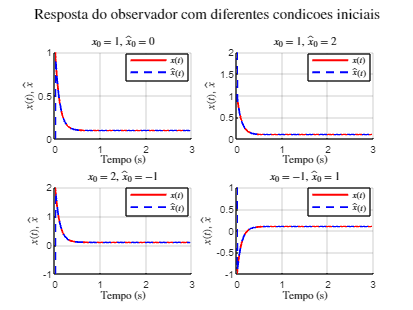

Q_o = eye(1); % Aumentar Q em relação a R: 
R_o = eye(1); % Aumentar R em relação a Q: 

[kalmf, L, P] = kalman(sys, Q_o, R_o);

% Matriz do sistema e observador (1x1)
Acl = Ac - L * Cc;
Aobserver = Acl;
Bobserver = [Bc L];
Cobserver = Cc; 
Dobserver = Dc;

% Criar sistema observador
sysObserver = ss(Aobserver, Bobserver, Cobserver, Dobserver);

input = ones(size(t8ms));
% Pares de condições iniciais: [x0_true, x0_obs]
init_pairs = [
    1, 0;
    1, 2;
    2, -1;
    -1, 1
];

% Figura com subplots
f = figure;
for i = 1:4
    x0true = init_pairs(i,1);
    x0obs  = init_pairs(i,2);

    % Simular sistema real
    [yTrue, timeTrue, xTrue] = lsim(sys, input, t8ms, x0true);

    % Entrada combinada u e y para o observador
    inputUY = [input; yTrue'];

    % Simular observador
    [yObserver, timeObserver, xObserver] = lsim(sysObserver, inputUY, t8ms, x0obs);

    % Plot
    subplot(2,2,i);
    hold on;
    plot(timeTrue, xTrue(:,1), 'r', 'LineWidth', 1.5, 'DisplayName', '$x(t)$');
    plot(timeObserver, xObserver(:,1), 'b--', 'LineWidth', 1.5, 'DisplayName', '$\hat{x}(t)$');
    title(sprintf('$x_0 = %g$, $\\hat{x}_0 = %g$', x0true, x0obs), 'Interpreter', 'latex');
    xlabel('Tempo (s)', 'Interpreter', 'latex');
    ylabel('$x(t)$, $\hat{x}$', 'Interpreter', 'latex');
    legend('Interpreter', 'latex', 'Location', 'best');
    grid on;
    hold off;
end

sgtitle('Resposta do observador com diferentes condicoes iniciais', 'Interpreter', 'latex');
exportgraphics(f, './Resultados/FiltroDeKalman.pdf', 'ContentType', 'vector');

#### III. Euler

[y_euler_cl, e_log_euler, e_hat_euler, u_euler, y_hat_euler, x_hat_euler] = ApplyControllerAndObserver(sys_euler, K, Ki, 0.001, N, Ts, R);

#### Resultados

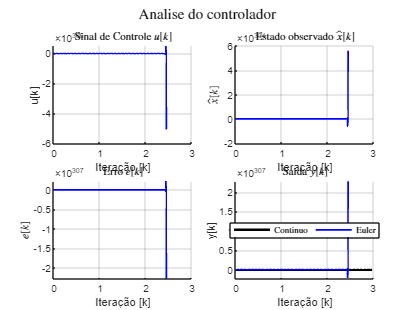

f = figure;

% --- Subplot 1: Sinal de Controle u[k]
subplot(2,2,1);
hold on;
plot(t, u_euler, 'b-', 'LineWidth', 1.5);
xlabel('Iteração [k]');
ylabel('u[k]');
title('Sinal de Controle $u[k]$', 'Interpreter', 'latex');
grid on;

% --- Subplot 2: Estado observado
subplot(2,2,2);
hold on;
plot(t, x_hat_euler, 'b-', 'LineWidth', 1.5);
xlabel('Iteração [k]');
ylabel('$\hat{x}[k]$', 'Interpreter', 'latex');
title('Estado observado $\hat{x}[k]$', 'Interpreter', 'latex');
grid on;

% --- Subplot 3: Erro
subplot(2,2,3);
hold on;
plot(t, e_log_euler, 'b-', 'LineWidth', 1.5);
xlabel('Iteração [k]');
ylabel('$e[k]$', 'Interpreter', 'latex');
title('Erro $e[k]$', 'Interpreter', 'latex');
grid on;

% --- Subplot 4: Saída
subplot(2,2,4);
hold on;
plot(t, y_cl * Kp, 'k-', 'LineWidth', 2, 'DisplayName', 'Continuo');
plot(t, y_euler_cl, 'b-', 'LineWidth', 1.5);
xlabel('Iteração [k]');
ylabel('y[k]');
title('Saida $y[k]$', 'Interpreter', 'latex');
grid on;

% Legenda global abaixo da figura
legend({'Continuo', 'Euler'}, ...
    'Orientation', 'horizontal', ...
    'Location', 'best', ...
    'Interpreter', 'latex');

sgtitle('Analise do controlador', 'Interpreter', 'latex');

% Exporta tudo em um único PDF
exportgraphics(f, './Resultados/AnaliseDoControlador.pdf', 'ContentType', 'vector');

Observador

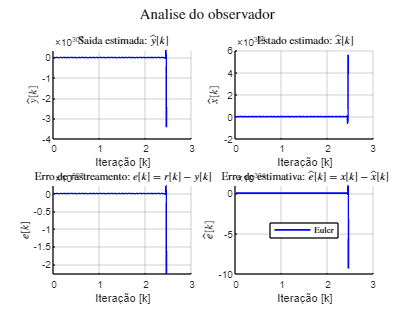

% Figura com 4 subplots
f = figure;

subplot(2,2,1);
hold on; 
plot(t, y_hat_euler, 'b-', 'LineWidth', 1.5);
hold off;
title('Saida estimada: $\hat{y}[k]$', 'Interpreter', 'latex');
xlabel('Iteração [k]');
ylabel('$\hat{y}[k]$', 'Interpreter', 'latex');
grid on;

% 2. Estado x vs x_hat (1ª componente)
subplot(2,2,2);
hold on;
plot(t, x_hat_euler, 'b-', 'LineWidth', 1.5);
hold off;
title('Estado estimado: $\hat{x}[k]$', 'Interpreter', 'latex');
xlabel('Iteração [k]');
ylabel('$\hat{x}[k]$', 'Interpreter', 'latex');
grid on;

% 3. Erro de rastreamento e = r - y
subplot(2,2,3);
hold on;
plot(t, e_log_euler, 'b-', 'LineWidth', 1.5);
hold off;
title('Erro de rastreamento: $e[k] = r[k] - y[k]$', 'Interpreter', 'latex');
xlabel('Iteração [k]');
ylabel('$e[k]$', 'Interpreter', 'latex');
grid on;

% 4. Erro de estimação ê = x - x̂ (1ª componente)
subplot(2,2,4);
hold on;
plot(t, e_hat_euler, 'b-', 'LineWidth', 1.5);
hold off;
title('Erro de estimativa: $\hat{e}[k] = x[k] - \hat{x}[k]$', 'Interpreter', 'latex');
xlabel('Iteração [k]');
ylabel('$\hat{e}[k]$', 'Interpreter', 'latex');
grid on;

% Legenda global abaixo da figura
lgd = legend({'Euler'}, ...
    'Orientation', 'horizontal', ...
    'Location', 'best', ...
    'Interpreter', 'latex');

% Título geral
sgtitle('Analise do observador', 'Interpreter', 'latex');

% Exporta para PDF vetorial
exportgraphics(f, './Resultados/AnaliseDoObservador.pdf', 'ContentType', 'vector');